# Redes Neuronales

# Aprendizaje no Supervisado

# Tarea 9

# Dataset Rings

**Realizado por: **David Fabián Cevallos Salas

**Fecha: **2023-08-29

tic
clc;
clear;
close all;
rng(0);
warning("off","all");

% Carga y limpieza de datos
datos = importdata("rings.txt");
X = datos(:,1:2);

% ---------------------------------------
% k-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-means")

k-means

fprintf("---------------------------------------")

---------------------------------------


n = 30

n = 30

k = 16

k = 16

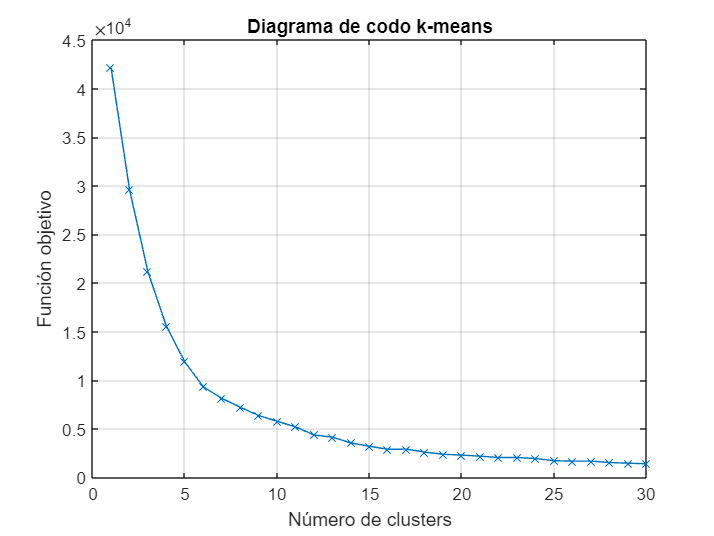

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    Jkm(i) = sum(SumD);
    Kkm(i) = i;
end

figure;
plot(Kkm, Jkm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

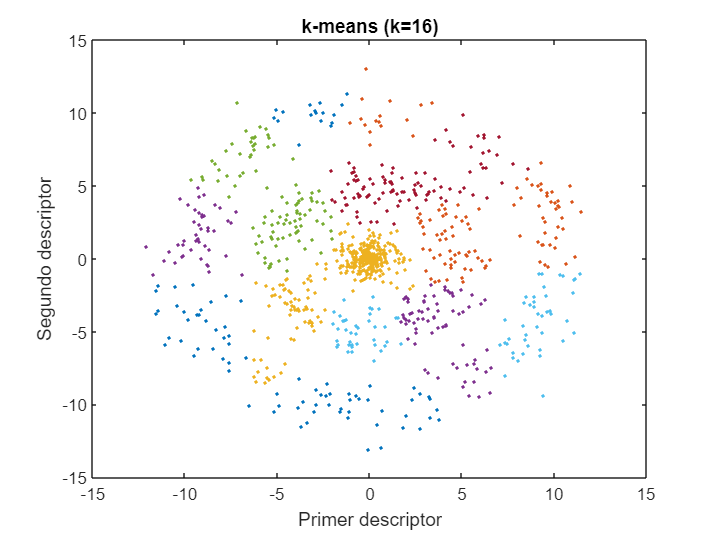


% Clustering
idx = kmeans(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-means (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-means")

Valores de métricas k-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 1.5138

SSB = 4.8630

WB = 4.9807

SIL = 0.6476



% ---------------------------------------
% k-medoids
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-medoids")

k-medoids

fprintf("---------------------------------------")

---------------------------------------


n = 30

n = 30

k = 16

k = 16

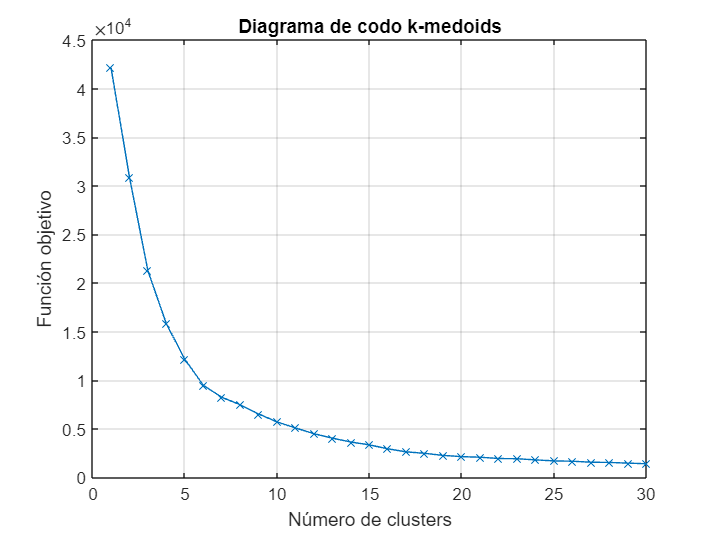

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    Jkmd(i) = sum(SumD);
    Kkmd(i) = i;
end

figure;
plot(Kkmd, Jkmd,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

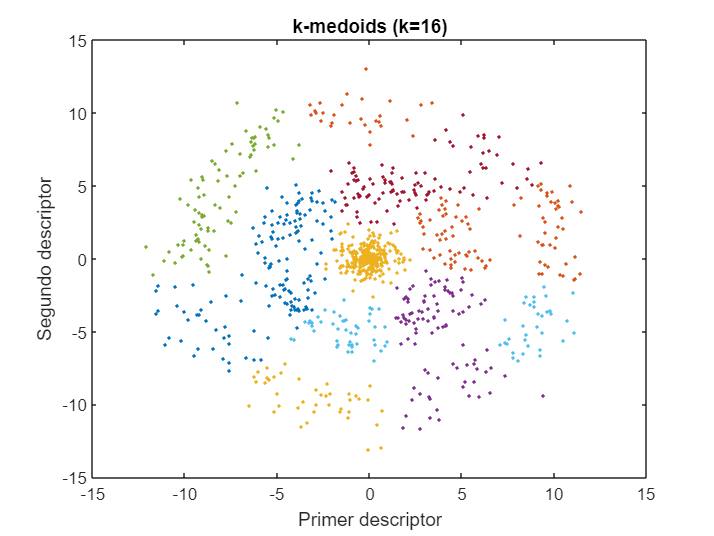


% Clustering
idx = kmedoids(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-medoids (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-medoids")

Valores de métricas k-medoids

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 1.4227

SSB = 4.8784

WB = 4.6661

SIL = 0.6948


% ---------------------------------------
% DBSCAN
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("DBSCAN")

DBSCAN

fprintf("---------------------------------------")

---------------------------------------

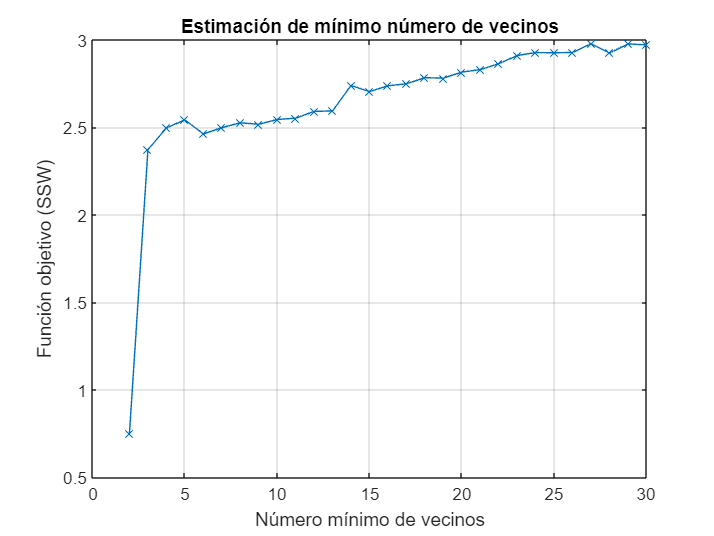


min_n = 23;
gmin_n = 2:1:30;

% Estimación número mínimo de vecinos
for i = 1:length(gmin_n)
    rng(0);
    min_ng = gmin_n(i);
    ep = clusterDBSCAN.estimateEpsilon(X,min_ng,min_ng);
    idx = dbscan(X,ep,min_ng);
    [SSWdb(i) SSBdb(i) WBdb(i) SILdb(i)] = MetricasNoSupervisado(X(idx>0,:),idx(idx>0));
    Kdb(i)=min_ng;
end

figure;
plot(Kdb,SSWdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (SSW)");
title("Estimación de mínimo número de vecinos");

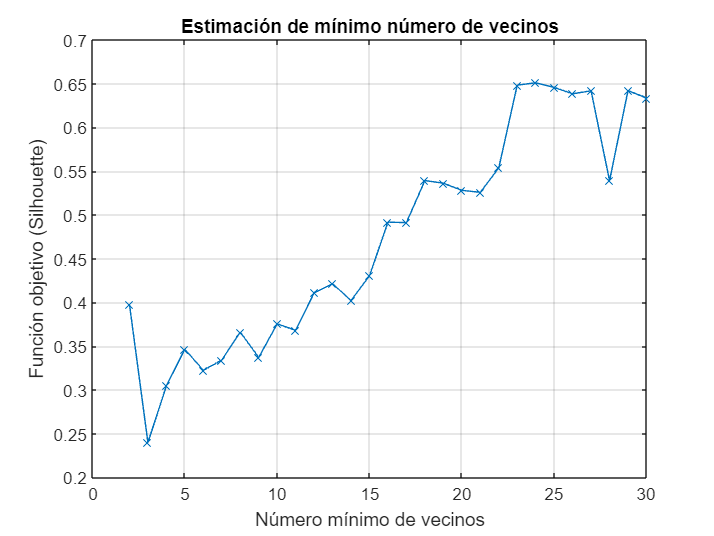


figure;
plot(Kdb,SILdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (Silhouette)");
title("Estimación de mínimo número de vecinos");



% Gráfica k-NN (Nearest Neigbor)
min_n

min_n = 23

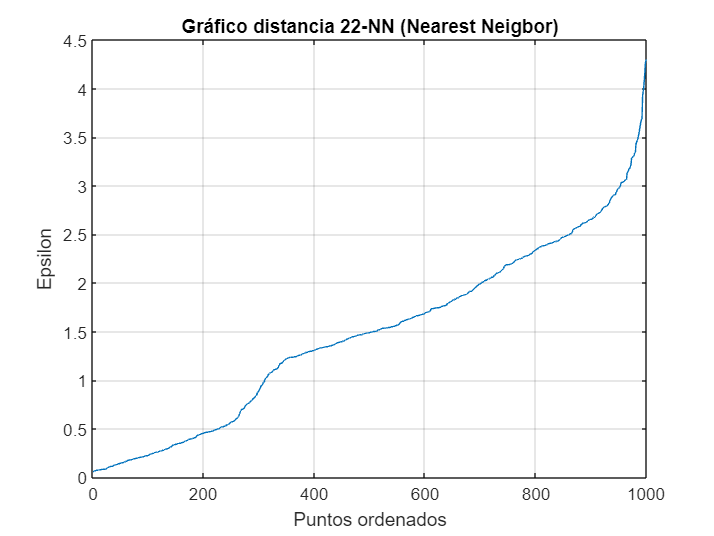

figure;
kD = pdist2(X,X,'euc','Smallest',min_n-1);
plot(sort(kD(end,:)));
title(strcat("Gráfico distancia ",string(min_n-1),"-NN (Nearest Neigbor)"));
xlabel("Puntos ordenados");
ylabel("Epsilon");
grid;


% Clustering
rng(0);
ep = clusterDBSCAN.estimateEpsilon(X,min_n,min_n)

ep = 1.7702

idx = dbscan(X,ep,min_n);
clusters = unique(idx(idx>0));
num_clusters = length(clusters)

num_clusters = 2

anomalias = length(idx(idx<=0));

if (anomalias>0)
    fprintf(strcat("Existen ",string(anomalias)," anomalías"));
else
    fprintf("No existen anomalías");
end

Existen 280 anomalías

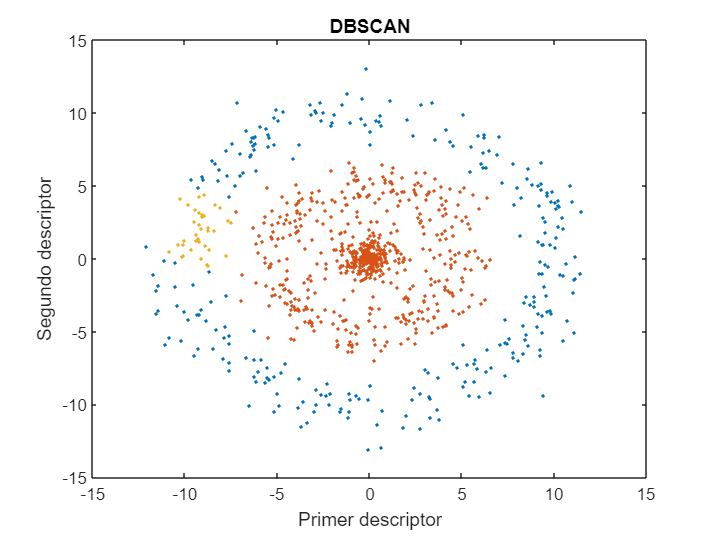


% Visualización de datos
figure;
for i=min(idx):max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("DBSCAN"));


% Métricas
fprintf("Valores de métricas DBSCAN")

Valores de métricas DBSCAN

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(idx>0,:),idx(idx>0))

SSW = 2.9111

SSB = 0.8809

WB = 6.6095

SIL = 0.6484


% ---------------------------------------
% Clustering Jerárquico
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Clustering Jerárquico")

Clustering Jerárquico

fprintf("---------------------------------------")

---------------------------------------


n = 30

n = 30

k = 16

k = 16

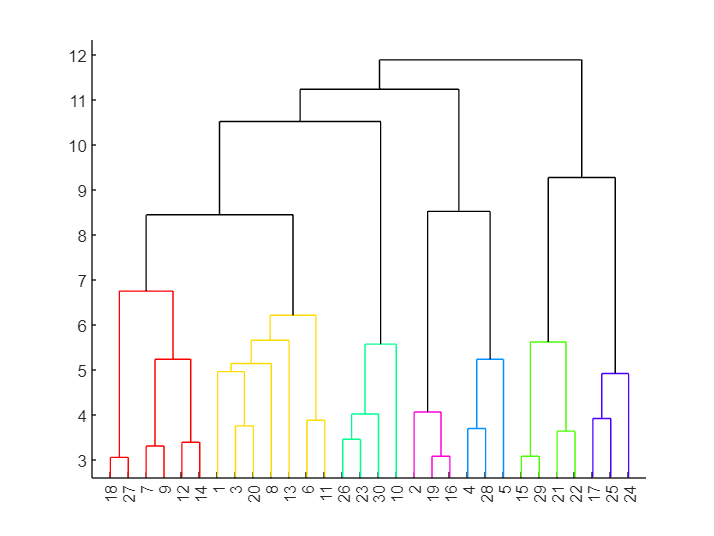

rng(0);

% Dendrograma
tree = linkage(X,"average","euclidean");
figure;
dendrogram(tree,"ColorThreshold","default")

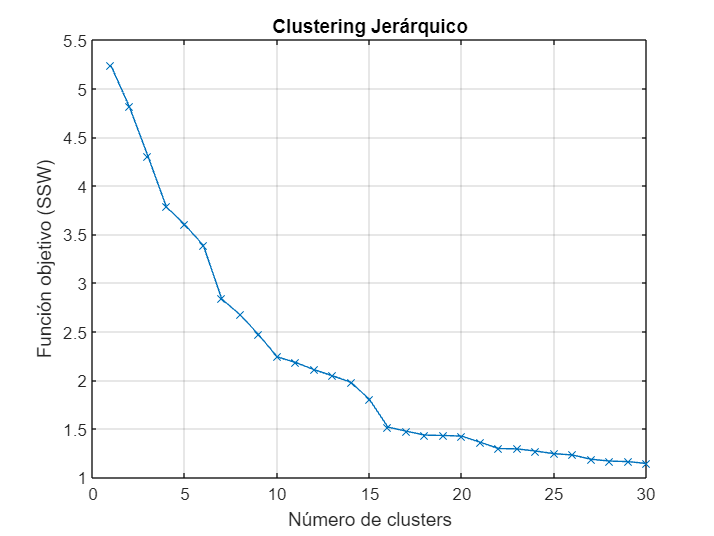


% Diagrama de codo
for i =1:n
    idx = cluster(tree,"maxclust",i);
    [SSWhc(i) SSBhc(i) WBhc(i) SILhc(i)] = MetricasNoSupervisado(X,idx);
    Khc(i)=i;
end

figure;
plot(Khc,SSWhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Clustering Jerárquico");

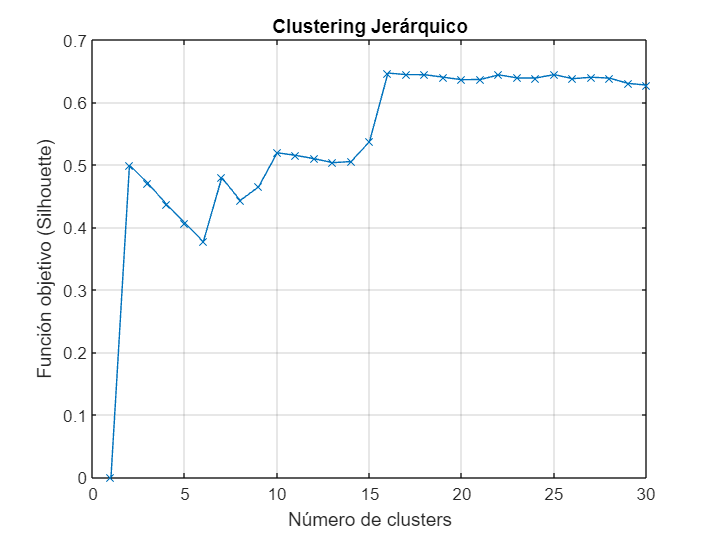


figure;
plot(Khc,SILhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (Silhouette)");
title("Clustering Jerárquico");

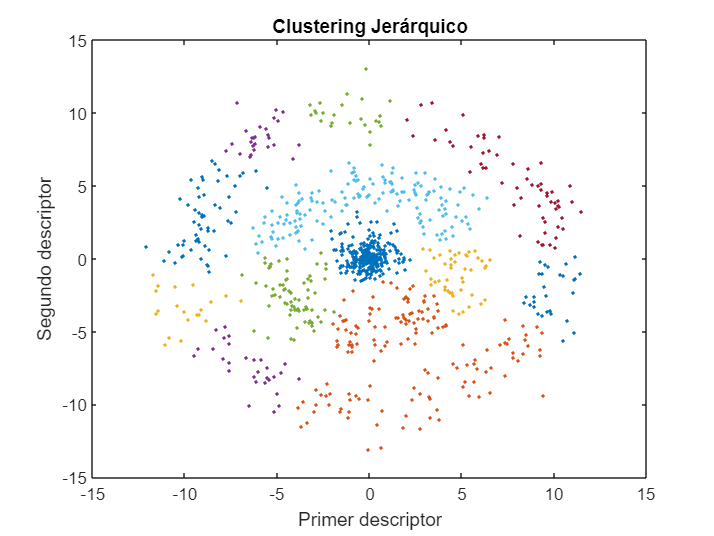


% Clusterización
idx = cluster(tree,"maxclust",k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title("Clustering Jerárquico");


% Métricas
fprintf("Valores de métricas Clustering Jerárquico")

Valores de métricas Clustering Jerárquico

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 1.5165

SSB = 4.8486

WB = 5.0043

SIL = 0.6471


% ---------------------------------------
% Fuzzy c-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Fuzzy c-means")

Fuzzy c-means

fprintf("---------------------------------------")

---------------------------------------


n=30

n = 30

c=16

c = 16

rng(0);

% Diagrama de codo
for i =1:n
    [centers,U] = fcm(X,i);
    Ut=U';
    idx= ones(length(Ut),1);
    maxU = max(U)';

    for j = 1:i
        s = Ut(:,j);
        f = find(s==maxU);
        idx(f)=j;
    end

    [SSWfcm(i) SSBfcm(i) WBfcm(i) SILfcm(i)] = MetricasNoSupervisado(X,idx);
    Kfcm(i)=i;
end

Iteration count = 1, obj. fcn = 0.057667
Iteration count = 2, obj. fcn = 0.000139
Iteration count = 3, obj. fcn = 0.000024
Iteration count = 4, obj. fcn = 0.000000
Iteration count = 5, obj. fcn = 0.000000
Minimum improvement reached.
Iteration count = 1, obj. fcn = 25687.360873
Iteration count = 2, obj. fcn = 21090.426692
Iteration count = 3, obj. fcn = 21085.797317
Iteration count = 4, obj. fcn = 21070.997213
Iteration count = 5, obj. fcn = 21031.954254
Iteration count = 6, obj. fcn = 20950.061931
Iteration count = 7, obj. fcn = 20813.919227
Iteration count = 8, obj. fcn = 20634.834701
Iteration count = 9, obj. fcn = 20452.884995
Iteration count = 10, obj. fcn = 20314.810255
Iteration count = 11, obj. fcn = 20236.757823
Iteration count = 12, obj. fcn = 20202.276240
Iteration count = 13, obj. fcn = 20189.290092
Iteration count = 14, obj. fcn = 20184.623047
Iteration count = 15, obj. fcn = 20182.784104
Iteration count = 16, obj. fcn = 20181.882073
Iteration count = 17, obj. fcn = 20181.

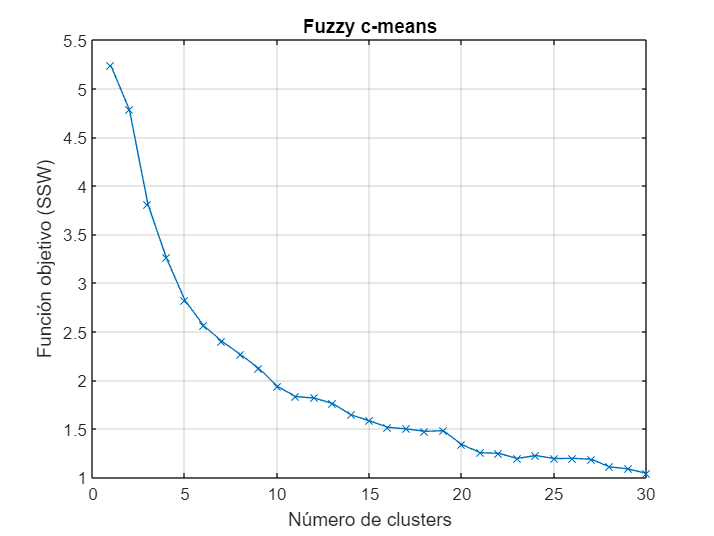


figure;
plot(Kfcm,SSWfcm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Fuzzy c-means");


% Clusterización
[centers,U] = fcm(X,c);

Iteration count = 1, obj. fcn = 3523.899664
Iteration count = 2, obj. fcn = 2633.771707
Iteration count = 3, obj. fcn = 2629.580485
Iteration count = 4, obj. fcn = 2621.412140
Iteration count = 5, obj. fcn = 2606.078408
Iteration count = 6, obj. fcn = 2575.052440
Iteration count = 7, obj. fcn = 2513.031759
Iteration count = 8, obj. fcn = 2417.590152
Iteration count = 9, obj. fcn = 2300.094099
Iteration count = 10, obj. fcn = 2173.898206
Iteration count = 11, obj. fcn = 2047.967097
Iteration count = 12, obj. fcn = 1927.682551
Iteration count = 13, obj. fcn = 1842.119889
Iteration count = 14, obj. fcn = 1777.607120
Iteration count = 15, obj. fcn = 1721.651770
Iteration count = 16, obj. fcn = 1675.821609
Iteration count = 17, obj. fcn = 1647.458612
Iteration count = 18, obj. fcn = 1628.343488
Iteration count = 19, obj. fcn = 1614.375862
Iteration count = 20, obj. fcn = 1602.563387
Iteration count = 21, obj. fcn = 1590.445352
Iteration count = 22, obj. fcn = 1575.436982
Iteration count = 2

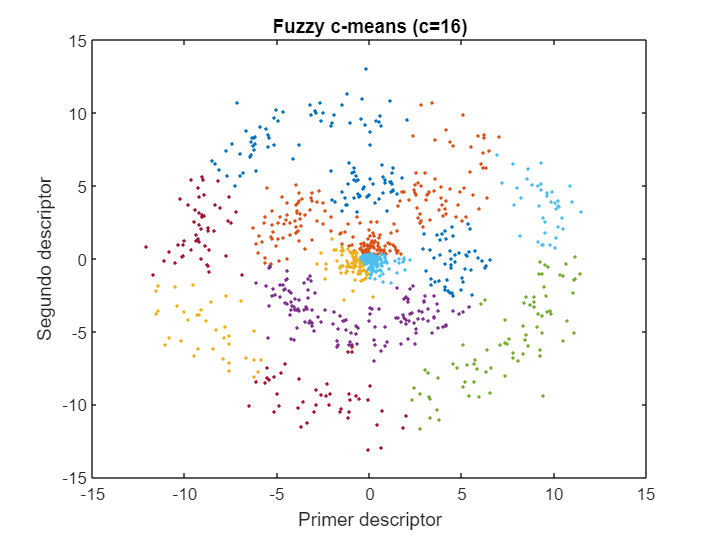

Ut=U';
idx= ones(length(Ut),1);
maxU = max(U)';

for i = 1:c
    s = Ut(:,i);
    f = find(s==maxU);
    idx(f)=i;
end

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("Fuzzy c-means (c=",string(c),")"));


% Métricas
fprintf("Valores de métricas Fuzzy c-means")

Valores de métricas Fuzzy c-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 1.4939

SSB = 5.0273

WB = 4.7546

SIL = 0.5016


toc

Elapsed time is 12.498154 seconds.
